# Filter Design

## FIR vs IIR for the same lowpass design problem

1) Compare FIR and IIR designs for the same practical spec

2) Show that the tool gives coefficients, but the engineer chooses trade-offs

3) Examine magnitude, phase, group delay, and rough computational cost

clear; close all; clc;

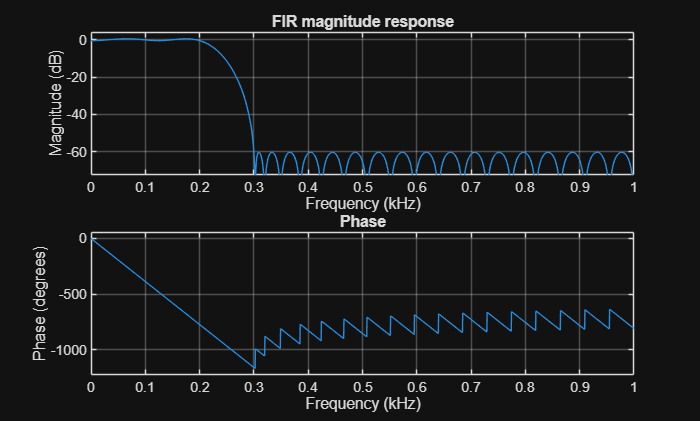

% "Design a lowpass filter for a 2 kHz-sampled signal.
% Keep 0-200 Hz with little distortion.
% Strongly suppress components above 300 Hz."

Fs = 2000;              % Hz
Fp = 200;               % passband edge (Hz)
Fst = 300;              % stopband edge (Hz)
Ap = 1;                 % passband ripple (dB)
Ast = 60;               % stopband attenuation (dB)

%% Build a test signal
t = 0:1/Fs:2;
x = 0.9*sin(2*pi*80*t) + 0.7*sin(2*pi*180*t) + 0.5*sin(2*pi*450*t) ...
    + 0.15*randn(size(t));

%% FIR design: linear-phase equiripple
dFIR = designfilt('lowpassfir', ...
    'PassbandFrequency', Fp, ...
    'StopbandFrequency', Fst, ...
    'PassbandRipple', Ap, ...
    'StopbandAttenuation', Ast, ...
    'SampleRate', Fs, ...
    'DesignMethod', 'equiripple'); % EQUIRIPPLE

%% IIR design: elliptic (small order, nonlinear phase)
dIIR = designfilt('lowpassiir', ...
    'PassbandFrequency', Fp, ...
    'StopbandFrequency', Fst, ...
    'PassbandRipple', Ap, ...
    'StopbandAttenuation', Ast, ...
    'SampleRate', Fs, ...
    'DesignMethod', 'ellip'); % ELLIP

%% FIR Magnitude responses
figure('Name','Magnitude responses');
freqz(dFIR, 2048, Fs);
title('FIR magnitude response');

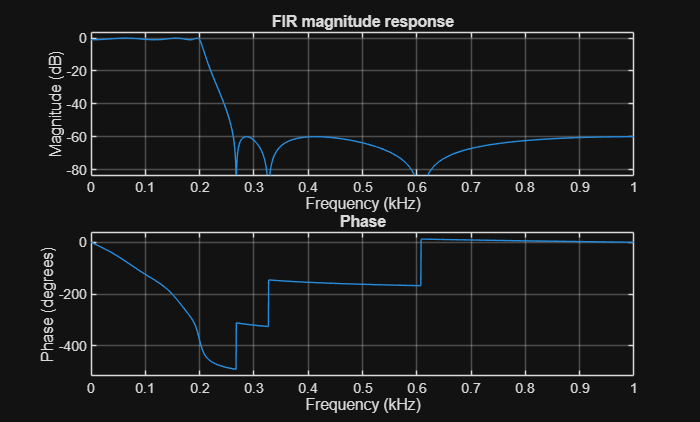

%% IIR Magnitude responses
figure('Name','Magnitude responses');
freqz(dIIR, 2048, Fs);
title('FIR magnitude response');

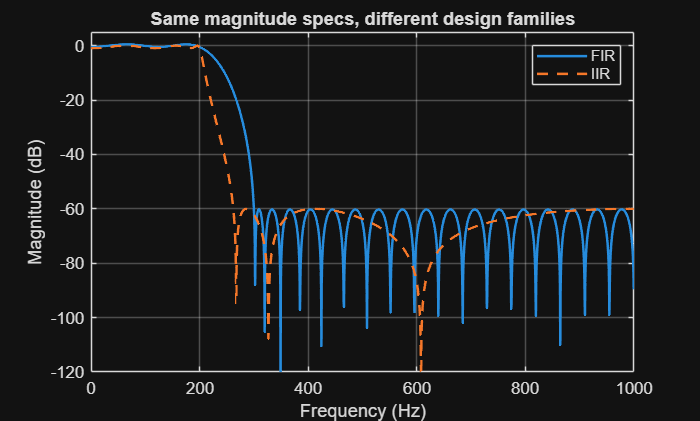

%% Compare both on one plot
% Compute the Frequency Response 
% (use freqz, with 2048 points, provide sample Frequency)

% Use [b,a] = tf(dFIR) or [b,a] = tf(dIIR) to get the LCCDE filter coefficients.
[bFIR, aFIR] = tf(dFIR) ;
[bIIR, aIIR] = tf(dIIR) ;

%% Filter the signal (use the filter command)
yFIR = filter(bFIR, aFIR, x);
yIIR = filter(bIIR, aIIR, x);

%% Frequency domain of the Transfer Function
[HFIR, f] = freqz(bFIR, aFIR, 2048, Fs);
[HIIR, ~] = freqz(bIIR, aIIR, 2048, Fs);

figure('Name','FIR vs IIR magnitude');
plot(f, 20*log10(abs(HFIR)+eps), 'LineWidth', 1.5); hold on;
plot(f, 20*log10(abs(HIIR)+eps), '--', 'LineWidth', 1.5);
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
legend('FIR', 'IIR');
title('Same magnitude specs, different design families');
ylim([-120 5]);

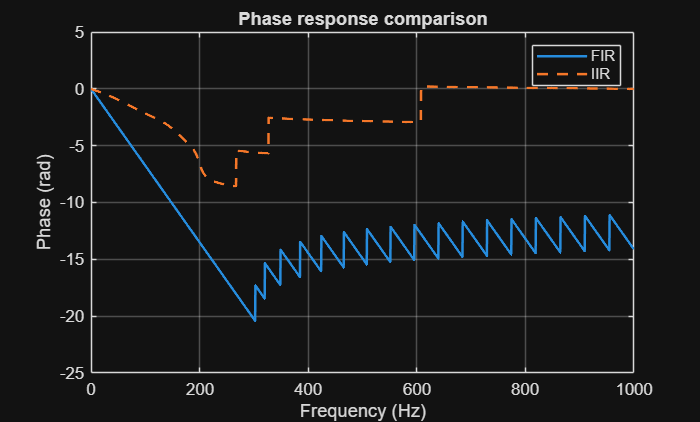

%% Phase comparison

% Phase of the transfer function in the frequency domain
phaseSpecFIR = unwrap(angle(HFIR));
phaseSpecIIR = unwrap(angle(HIIR));

figure('Name','Phase comparison');
plot(f, phaseSpecFIR, 'LineWidth', 1.5); hold on;
plot(f, phaseSpecIIR, '--', 'LineWidth', 1.5);
grid on;
xlabel('Frequency (Hz)');
ylabel('Phase (rad)');
legend('FIR', 'IIR');
title('Phase response comparison');

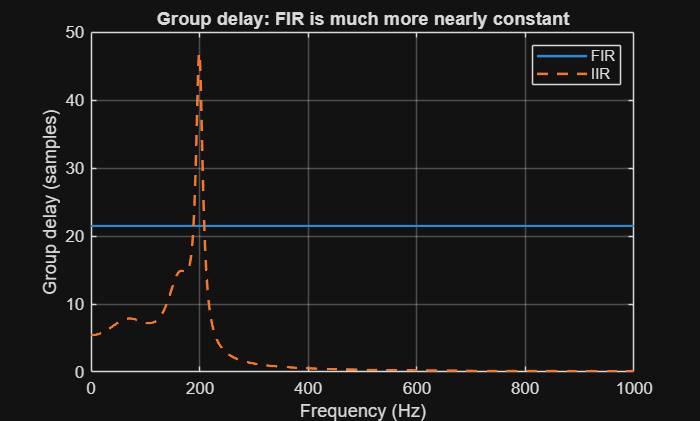

%% Group delay comparison
% Use MATLAB group delay function: grpdelay
% Use 2048 points and supply sample rate

% Frequency components delayed by a signal.
[gdFIR, fg1] = grpdelay(bFIR, aFIR, 2048, Fs) ;
[gdIIR, fg2] = grpdelay(bIIR, aIIR, 2048, Fs) ;

figure('Name','Group delay comparison');
plot(fg1, gdFIR, 'LineWidth', 1.5); hold on;
plot(fg2, gdIIR, '--', 'LineWidth', 1.5);
grid on;
xlabel('Frequency (Hz)');
ylabel('Group delay (samples)');
legend('FIR', 'IIR');
title('Group delay: FIR is much more nearly constant');

## **Visualization 1: Spectrum Before and After Filtering**

This is the clearest way to show that lowpass filtering worked.

We plot only the positive-frequency half of the FFT.

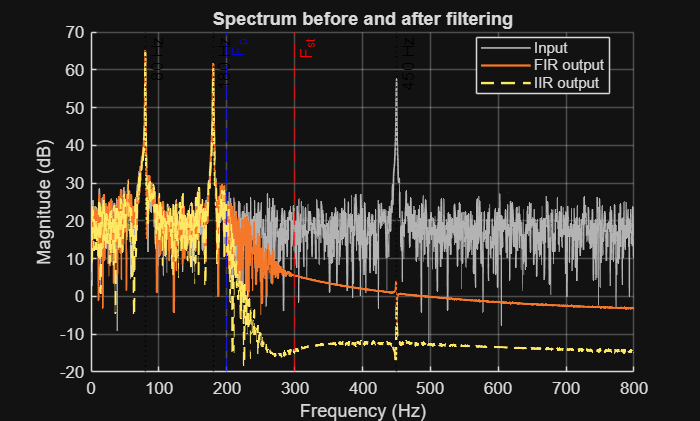

Nfft = 4096;

% (FAST FOURIER TRANSFORM) fft to compute the spectrum now
% Use Nfft points to compute the fft
% We do not need fftshift because we take only the positive-frequency half

X    = fft(x, Nfft); % input spectrum
YFIR = fft(yFIR, Nfft); % output spectrum FIR
YIIR = fft(yIIR, Nfft); % output spectrum IIR

f = (0:Nfft-1)*(Fs/Nfft);
fplot = f(1:Nfft/2);

figure('Name','Spectral comparison');

hold on;

% Store handles for the three spectra so the legend stays clean
hIn = plot(fplot, 20*log10(abs(X(1:Nfft/2))+eps), ...
    'Color', [0.7 0.7 0.7], 'LineWidth', 1.0);

hFIR = plot(fplot, 20*log10(abs(YFIR(1:Nfft/2))+eps), ...
    'LineWidth', 1.4);

hIIR = plot(fplot, 20*log10(abs(YIIR(1:Nfft/2))+eps), '--', ...
    'LineWidth', 1.4);

grid on;

xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Spectrum before and after filtering');
xlim([0 800]);

% Optional markers to guide students
xline(80,  ':k', '80 Hz');
xline(180, ':k', '180 Hz');
xline(450, ':k', '450 Hz');
xline(Fp,  '--b', 'F_p');
xline(Fst, '--r', 'F_{st}');

% Only include the three main curves in the legend
legend([hIn hFIR hIIR], {'Input','FIR output','IIR output'}, ...
    'Location', 'Best');

## **Visualisation 2: Time-Domain Zoom with FIR Delay Compensation**

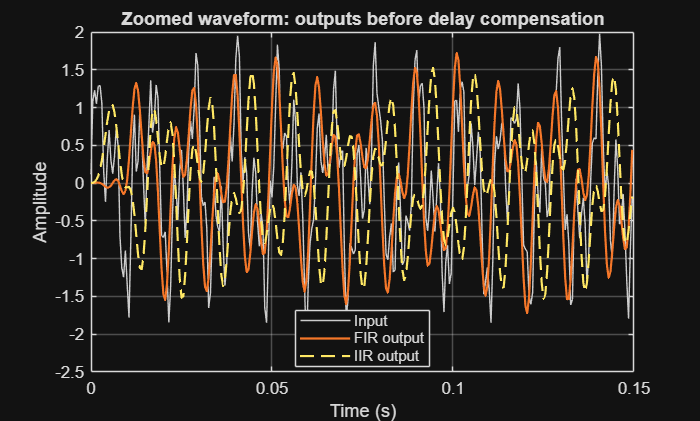

% Estimate FIR group delay in samples
% Use grpdelay
[gd,~] = grpdelay(bFIR, aFIR, 2048, Fs); 
firDelay = round(mean(gd));

% Delay-compensated FIR output for visual comparison only
yFIR_align = yFIR;
if firDelay < length(yFIR_align)
    yFIR_align(1:end-firDelay) = yFIR(firDelay+1:end);
    yFIR_align(end-firDelay+1:end) = NaN;
end

% Zoom into a short time region
idx = 1:300;   % about 0.15 s at Fs = 2000

figure('Name','Zoomed time comparison');
plot(t(idx), x(idx), 'Color', [0.8 0.8 0.8]); hold on;
plot(t(idx), yFIR(idx), 'LineWidth', 1.3);
plot(t(idx), yIIR(idx), '--', 'LineWidth', 1.3);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
legend('Input','FIR output','IIR output','Location','Best');
title('Zoomed waveform: outputs before delay compensation');

## Visualisation 3: Transient / Burst Test

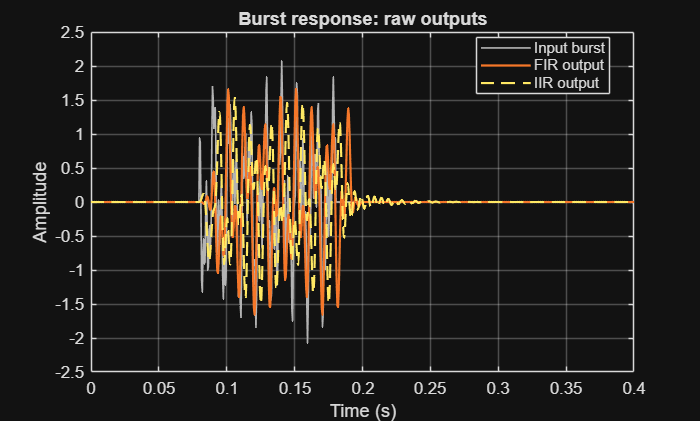

%% ------------------------------------------------------------
%% VISUALIZATION 3: TRANSIENT / BURST TEST
%% ------------------------------------------------------------
% Nonlinear phase is easier to see on bursts and waveform edges.

tb = 0:1/Fs:0.4;
xBurst = zeros(size(tb));

% A short burst with multiple components
burstIdx = tb >= 0.08 & tb <= 0.18;
xBurst(burstIdx) = 0.9*sin(2*pi*80*tb(burstIdx)) ...
                 + 0.7*sin(2*pi*180*tb(burstIdx)) ...
                 + 0.5*sin(2*pi*450*tb(burstIdx));

% Use the filter command to filter the burst signal
yBurstFIR = filter(bFIR, aFIR, xBurst); 
yBurstIIR = filter(bIIR, aIIR, xBurst) ;

% FIR delay compensation for display
yBurstFIR_align = yBurstFIR;
if firDelay < length(yBurstFIR_align)
    yBurstFIR_align(1:end-firDelay) = yBurstFIR(firDelay+1:end);
    yBurstFIR_align(end-firDelay+1:end) = NaN;
end

figure('Name','Burst response');
plot(tb, xBurst, 'Color', [0.7 0.7 0.7], 'LineWidth', 1.0); hold on;
plot(tb, yBurstFIR, 'LineWidth', 1.3);
plot(tb, yBurstIIR, '--', 'LineWidth', 1.3);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
legend('Input burst','FIR output','IIR output','Location','Best');
title('Burst response: raw outputs');

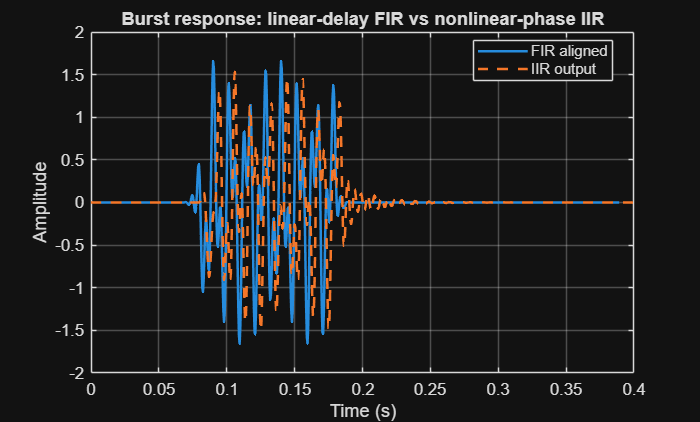


figure('Name','Burst response with FIR aligned');
plot(tb, yBurstFIR_align, 'LineWidth', 1.5); hold on;
plot(tb, yBurstIIR, '--', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
legend('FIR aligned','IIR output','Location','Best');
title('Burst response: linear-delay FIR vs nonlinear-phase IIR');


%% Rough implementation cost comparison
% For a direct-form FIR, multiplies per sample is roughly filter order + 1.
% For IIR, cost depends on realization, but order is much lower.
% Use filtord to determine the order of the filter (number of coefficients)
firOrder = filtord(bFIR, aFIR);
iirOrder = filtord(bIIR, aIIR);

fprintf('FIR order = %d\n', firOrder);

FIR order = 43


fprintf('IIR order = %d\n', iirOrder);

IIR order = 6


fprintf('Approx FIR multiplications/sample ~ %d\n', firOrder + 1);

Approx FIR multiplications/sample ~ 44


fprintf('IIR order is much smaller, so implementation is usually cheaper.\n')

IIR order is much smaller, so implementation is usually cheaper.


# FIR Filter Design Comparison

This script is designed to teach FIR design methods clearly.

It has two parts:

**Part A: Same order, different methods**

   - Hamming window

   - Kaiser window

   - Least squares

   - Equiripple

   - Least-Pth norm

These are compared using the same FIR order so students can see how each method distributes error differently.

**Part B: Same broad specification using designfilt**

   - Kaiser window

   - Least squares

   - Constrained least squares

   - Equiripple

   - Least-Pth norm

This teaches what MATLAB's design engines do when given the same design goal.

clear; close all; clc;

**Common specifications**

Fs  = 2000;     % Sampling frequency (Hz)
Fp  = 300;      % Passband edge (Hz)
Fst = 420;      % Stopband edge (Hz)

Ap_dB  = 1;     % Desired passband ripple (dB)
Ast_dB = 60;    % Desired stopband attenuation (dB)

Nfft = 4096;

fprintf('Fs = %g Hz, Fp = %g Hz, Fst = %g Hz\n', Fs, Fp, Fst);

Fs = 2000 Hz, Fp = 300 Hz, Fst = 420 Hz


## PART A: Same order, different methods

N = 50;   % Common FIR order

### `1. Window-based FIR designs (fir1)`

`fir1 requires a normalized cutoff frequency Wn in [0,1], where 1 corresponds to the Nyquist frequency (Fs/2).`

`IMPORTANT:`

`fir1 does NOT directly use passband and stopband edges.`

`It expects a "cutoff" that roughly sits in the transition region. So we choose the midpoint between Fp and Fst.`

Wn_mid = ((Fp + Fst)/2) / (Fs/2);   % Normalize midpoint frequency to Nyquist

**Hamming Window design**

% Inputs:
%   N              → filter order (number of taps = N+1)
%   Wn_mid         → normalized cutoff frequency (0 to 1)
%   hamming(N+1)   → window shape applied to ideal impulse response

% Effect:
%   Smooth transition band
%   Moderate stopband attenuation (~50 dB)
%   Linear phase (constant group delay)

b_hamming = fir1(N, Wn_mid, hamming(N+1)) ;  

**Kaiser window design**

% Inputs:
%   N                 → filter order
%   Wn_mid            → normalized cutoff
%   kaiser(N+1,beta)  → adjustable window

% beta:
%   larger beta → better stopband attenuation, wider transition
%   smaller beta → sharper transition, worse stopband

% Effect:
%   More flexible than Hamming (tunable performance)

beta = 6; % controls trade-off between mainlobe width and sidelobe level
b_kaiser = fir1(N, Wn_mid, kaiser(N+1, beta)) ; % fir1

### `2. Least-squares FIR design (firls)`

`frequency vector normalised to Nyquist`

% Meaning:
%   0       → DC
%   Fp      → passband edge
%   Fst     → stopband edge
%   Fs/2    → Nyquist frequency

% After normalization:
%   values lie in [0,1]

f = [0 Fp Fst Fs/2] / (Fs/2);

% ---------------------------

% Meaning:
%   from 0 to Fp  → gain = 1 (passband)
%   from Fst to Fs/2 → gain = 0 (stopband)

% Between Fp and Fst:
%   transition band (not strictly enforced)

% Desired amplitude at each frequency point

a = [1 1 0 0];

% ---------------------------

% Inputs:
%   N  → filter order
%   f  → frequency breakpoints
%   a  → desired amplitude at those frequencies

% Design method:
%   Minimizes integrated squared error:
%       ∫ |H_d(ω) - H(ω)|^2 dω

% Effect:
%   Smooth error distribution
%   No sharp ripple equalization
%   Linear phase

% Use firls

b_ls = firls(N, f, a) ;

### `3. Equiripple FIR design (firpm)`

% Inputs:
%   N  → filter order
%   f  → frequency breakpoints
%   a  → desired amplitude

% Design method:
%   Minimize maximum error (minimax problem):
%       max |H_d(ω) - H(ω)|

% Effect:
%   Ripple is equalized across bands ("equiripple")
%   Best worst-case performance
%   Sharpest transition for given N
%   Linear phase

% Use firpm

b_eq = firpm(N, f, a) ;

### `4. Least-Pth norm`

IMPORTANT:

p must be a vector [pmin pmax], not a scalar.

The idea is that MATLAB gradually moves from a lower p, hence:

(closer to least-squares) toward a larger p

(closer to minimax/equiripple).

% MATLAB firlpnorm syntax requires:

% b = firlpnorm(n, f, edges, a, w, p, dens, initnum)

try
    f_lp     = [0 Fp Fst Fs/2] / (Fs/2);
    edges_lp = [0 Fp Fst Fs/2] / (Fs/2);
    a_lp     = [1 1 0 0];
    w_lp     = [1 1 1 1];
    p_lp     = [2 10];      % FIXED: must be [pmin pmax]
    dens_lp  = 30;
    % Use firlpnorm - don't forget the filter order N
    b_lp = firlpnorm(N, f_lp, edges_lp, a_lp, w_lp, p_lp, dens_lp) ;
    hasLP = true;
catch ME
    warning('firlpnorm failed: %s', ME.message);
    hasLP = false;
end

## Frequency responses for Part A

% Use freqz on filter coefficients with NFFT and Fs
[H_ham, ff] = freqz(b_hamming, 1, Nfft, Fs);
[H_kai, ~]  = freqz(b_kaiser, 1, Nfft, Fs);
[H_ls, ~]   = freqz(b_ls, 1, Nfft, Fs);
[H_eq, ~]   = freqz(b_eq, 1, Nfft, Fs);

if hasLP
    [H_lp, ~] = freqz(b_lp, 1, Nfft, Fs);
end

### `Full magnitude plot`

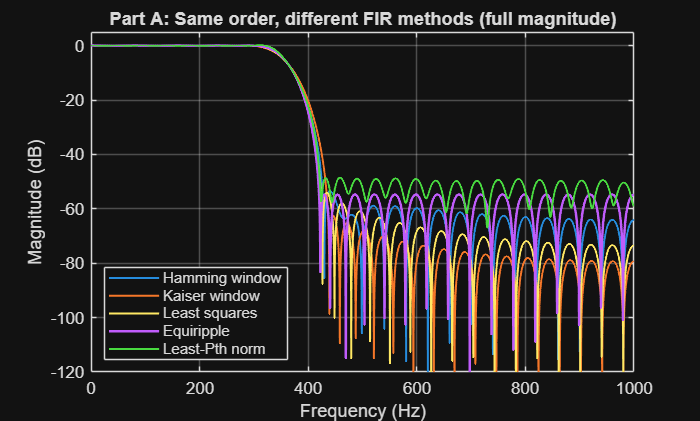

figure('Name','Part A: Full magnitude');
plot(ff, 20*log10(abs(H_ham)+eps), 'LineWidth', 1.2); hold on;
plot(ff, 20*log10(abs(H_kai)+eps), 'LineWidth', 1.2);
plot(ff, 20*log10(abs(H_ls)+eps),  'LineWidth', 1.2);
plot(ff, 20*log10(abs(H_eq)+eps),  'LineWidth', 1.5);
if hasLP
    plot(ff, 20*log10(abs(H_lp)+eps), 'LineWidth', 1.2);
end
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Part A: Same order, different FIR methods (full magnitude)');
ylim([-120 5]);

legA = {'Hamming window','Kaiser window','Least squares','Equiripple'};
if hasLP
    legA{end+1} = 'Least-Pth norm';
end
legend(legA, 'Location', 'SouthWest');

### `Passband zoom`

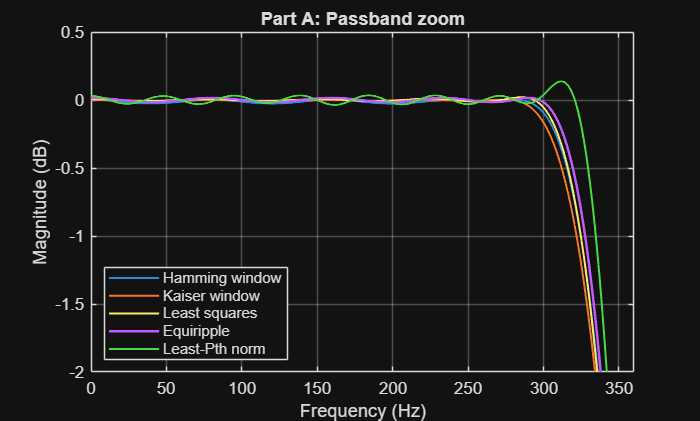

figure('Name','Part A: Passband zoom');
plot(ff, 20*log10(abs(H_ham)+eps), 'LineWidth', 1.2); hold on;
plot(ff, 20*log10(abs(H_kai)+eps), 'LineWidth', 1.2);
plot(ff, 20*log10(abs(H_ls)+eps),  'LineWidth', 1.2);
plot(ff, 20*log10(abs(H_eq)+eps),  'LineWidth', 1.5);
if hasLP
    plot(ff, 20*log10(abs(H_lp)+eps), 'LineWidth', 1.2);
end
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Part A: Passband zoom');
xlim([0 360]);
ylim([-2 0.5]);
legend(legA, 'Location', 'SouthWest');

### `Transition-band zoom`

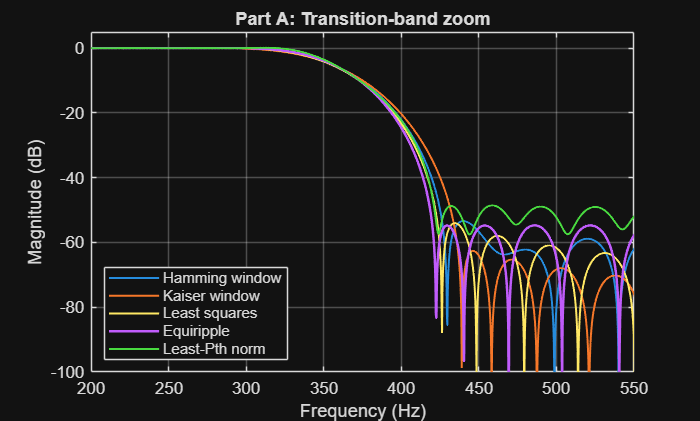

figure('Name','Part A: Transition zoom');
plot(ff, 20*log10(abs(H_ham)+eps), 'LineWidth', 1.2); hold on;
plot(ff, 20*log10(abs(H_kai)+eps), 'LineWidth', 1.2);
plot(ff, 20*log10(abs(H_ls)+eps),  'LineWidth', 1.2);
plot(ff, 20*log10(abs(H_eq)+eps),  'LineWidth', 1.5);
if hasLP
    plot(ff, 20*log10(abs(H_lp)+eps), 'LineWidth', 1.2);
end
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Part A: Transition-band zoom');
xlim([200 550]);
ylim([-100 5]);
legend(legA, 'Location', 'SouthWest');

### Stopband zoom

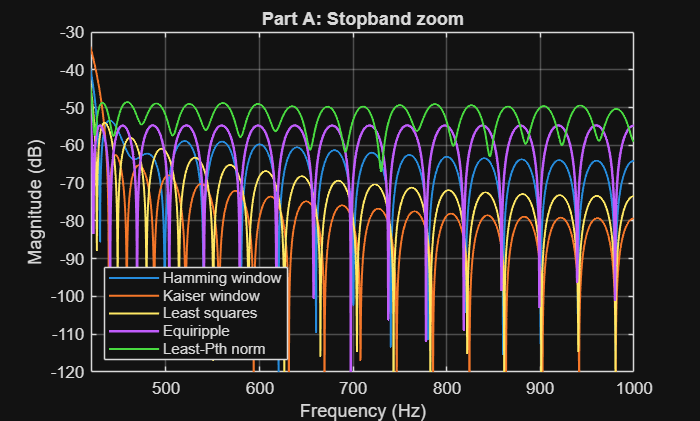

figure('Name','Part A: Stopband zoom');
plot(ff, 20*log10(abs(H_ham)+eps), 'LineWidth', 1.2); hold on;
plot(ff, 20*log10(abs(H_kai)+eps), 'LineWidth', 1.2);
plot(ff, 20*log10(abs(H_ls)+eps),  'LineWidth', 1.2);
plot(ff, 20*log10(abs(H_eq)+eps),  'LineWidth', 1.5);
if hasLP
    plot(ff, 20*log10(abs(H_lp)+eps), 'LineWidth', 1.2);
end
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Part A: Stopband zoom');
xlim([420 Fs/2]);
ylim([-120 -30]);
legend(legA, 'Location', 'SouthWest');

### Group delay

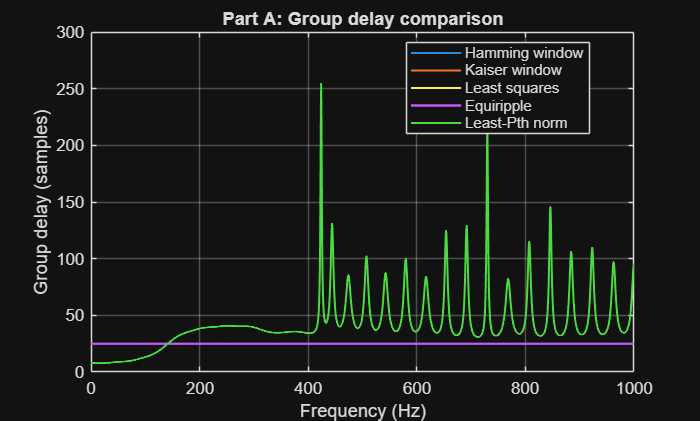

[gd_ham, fg] = grpdelay(b_hamming, 1, 2048, Fs);
[gd_kai, ~]  = grpdelay(b_kaiser, 1, 2048, Fs);
[gd_ls, ~]   = grpdelay(b_ls, 1, 2048, Fs);
[gd_eq, ~]   = grpdelay(b_eq, 1, 2048, Fs);
if hasLP
    [gd_lp, ~] = grpdelay(b_lp, 1, 2048, Fs);
end

figure('Name','Part A: Group delay');
plot(fg, gd_ham, 'LineWidth', 1.2); hold on;
plot(fg, gd_kai, 'LineWidth', 1.2);
plot(fg, gd_ls,  'LineWidth', 1.2);
plot(fg, gd_eq,  'LineWidth', 1.5);
if hasLP
    plot(fg, gd_lp, 'LineWidth', 1.2);
end
grid on;
xlabel('Frequency (Hz)');
ylabel('Group delay (samples)');
title('Part A: Group delay comparison');
legend(legA, 'Location', 'Best');

Hamming, Kaiser, LS, Equiripple -> almost flast group delay

Least-Pth norm -> wild spikes in the stopband

Group delay in unreliable when the $|H(e^{j \omega})| \approx 0$. Phase becomes ill-defined, tiny numerical changes imply huge phase jumps because derivative of phase blows up (Recall: $\tau(\omega) = -\frac{d}{d\omega}\text{arg}H(e^{j \omega})$). To reduce maximum error, the filter puts notches in the stopband and places zeros near the unit circle. At those frequencies $|H(e^{j \omega})| \approx 0$ and group delay spikes. These are not physically meaningful delays. Let's now replot with a mask for the passband only.

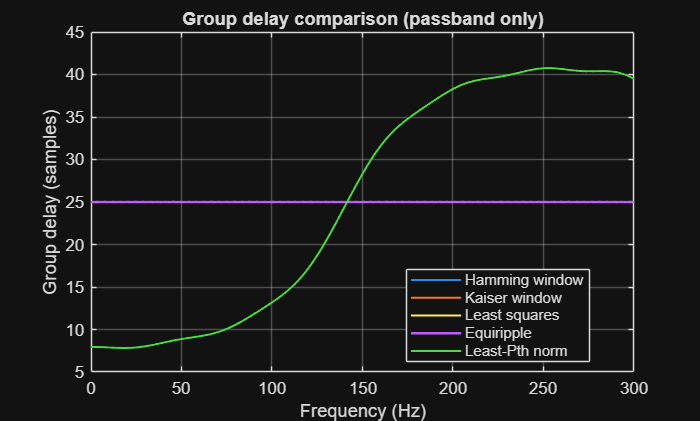

mask = fg <= Fp;   % only passband

figure('Name','Group delay (passband only)');
plot(fg(mask), gd_ham(mask), 'LineWidth', 1.2); hold on;
plot(fg(mask), gd_kai(mask), 'LineWidth', 1.2);
plot(fg(mask), gd_ls(mask),  'LineWidth', 1.2);
plot(fg(mask), gd_eq(mask),  'LineWidth', 1.5);
if hasLP
    plot(fg(mask), gd_lp(mask), 'LineWidth', 1.2);
end
grid on;
xlabel('Frequency (Hz)');
ylabel('Group delay (samples)');
title('Group delay comparison (passband only)');
legend(legA, 'Location', 'Best');

## PART B: Same Specifications Using Designfilt

methods = {};
H_list = {};
orders = [];

**KAISER WINDOW**

try
    d_kaiser = designfilt('lowpassfir', ...
        'PassbandFrequency', Fp, ...
        'StopbandFrequency', Fst, ...
        'PassbandRipple', Ap_dB, ...
        'StopbandAttenuation', Ast_dB, ...
        'SampleRate', Fs, ...
        'DesignMethod', 'kaiserwin');

    [b,a_den] = tf(d_kaiser);
    [H, ff2] = freqz(b, a_den, Nfft, Fs);
    methods{end+1} = 'kaiserwin';
    H_list{end+1} = H;
    orders(end+1) = filtord(d_kaiser);
catch ME
    warning('kaiserwin failed: %s', ME.message);
end

**LEAST SQUARES**

try
    d_ls = designfilt('lowpassfir', ...
        'PassbandFrequency', Fp, ...
        'StopbandFrequency', Fst, ...
        'FilterOrder', 50, ...
        'SampleRate', Fs, ...
        'DesignMethod', 'ls');

    [b,a_den] = tf(d_ls);
    [H, ff2] = freqz(b, a_den, Nfft, Fs);
    methods{end+1} = 'ls';
    H_list{end+1} = H;
    orders(end+1) = filtord(d_ls);
catch ME
    warning('ls failed: %s', ME.message);
end

**EQUIRIPPLE**

try
    d_eq = designfilt('lowpassfir', ...
        'PassbandFrequency', Fp, ...
        'StopbandFrequency', Fst, ...
        'PassbandRipple', Ap_dB, ...
        'StopbandAttenuation', Ast_dB, ...
        'SampleRate', Fs, ...
        'DesignMethod', 'equiripple');

    [b,a_den] = tf(d_eq);
    [H, ff2] = freqz(b, a_den, Nfft, Fs);
    methods{end+1} = 'equiripple';
    H_list{end+1} = H;
    orders(end+1) = filtord(d_eq);
catch ME
    warning('equiripple failed: %s', ME.message);
end

**Plot Part B full magnitude**

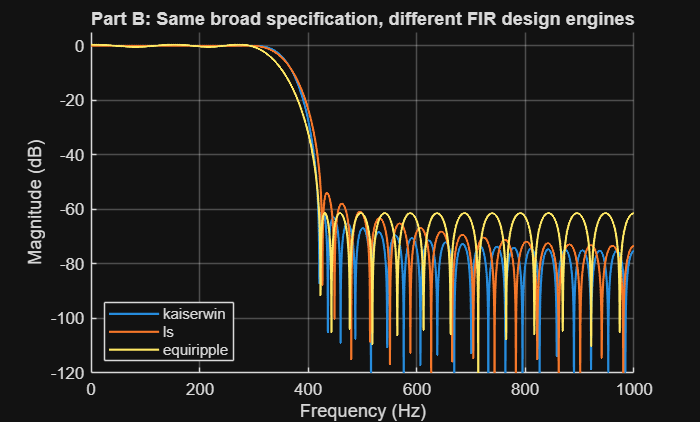

figure('Name','Part B: Same spec via designfilt');
hold on;
for k = 1:numel(H_list)
    plot(ff2, 20*log10(abs(H_list{k})+eps), 'LineWidth', 1.3);
end
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Part B: Same broad specification, different FIR design engines');
ylim([-120 5]);
legend(methods, 'Location', 'SouthWest');

**Passband zoom**

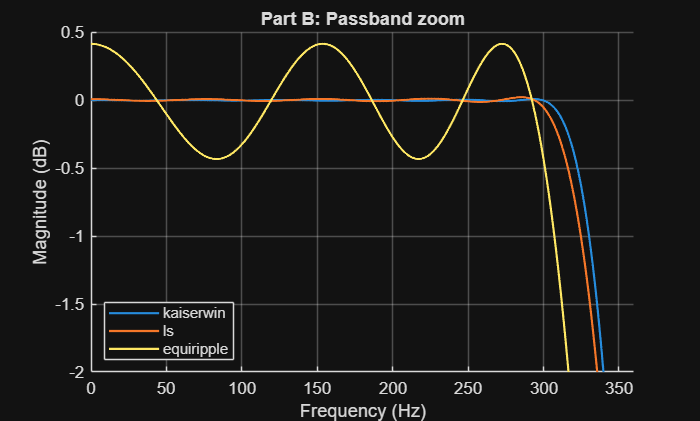

figure('Name','Part B: Passband zoom');
hold on;
for k = 1:numel(H_list)
    plot(ff2, 20*log10(abs(H_list{k})+eps), 'LineWidth', 1.3);
end
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Part B: Passband zoom');
xlim([0 360]);
ylim([-2 0.5]);
legend(methods, 'Location', 'SouthWest');

**Transition zoom**

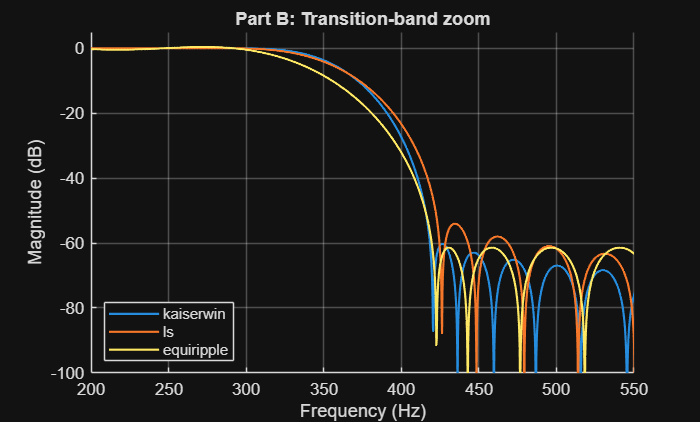

figure('Name','Part B: Transition zoom');
hold on;
for k = 1:numel(H_list)
    plot(ff2, 20*log10(abs(H_list{k})+eps), 'LineWidth', 1.3);
end
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('Part B: Transition-band zoom');
xlim([200 550]);
ylim([-100 5]);
legend(methods, 'Location', 'SouthWest');

**Show orders**

fprintf('\nPart B summary: same broad specification\n');


Part B summary: same broad specification


for k = 1:numel(methods)
    fprintf('%12s : order %d\n', methods{k}, orders(k));
end

   kaiserwin : order 62
          ls : order 50
  equiripple : order 36


Observe:

-  which method achieved the target most efficiently - Equiripple

-  which method gives the smallest order - Equiripple

# FIR Filter Design with Non-Flat Passband Peak

### DIRECT firlpnorm EXAMPLE WITH NON-FLAT PASSBAND PEAK

- **firlpnorm example:**

non-flat passband shaping

- **Goal:**

Design an FIR lowpass filter whose passband is NOT flat, but instead has a peak (gain = 1.4) within the passband.

- **General form:**

b = firlpnorm(n, f, edges, a, w, p) ... where each argument has a specific meaning.

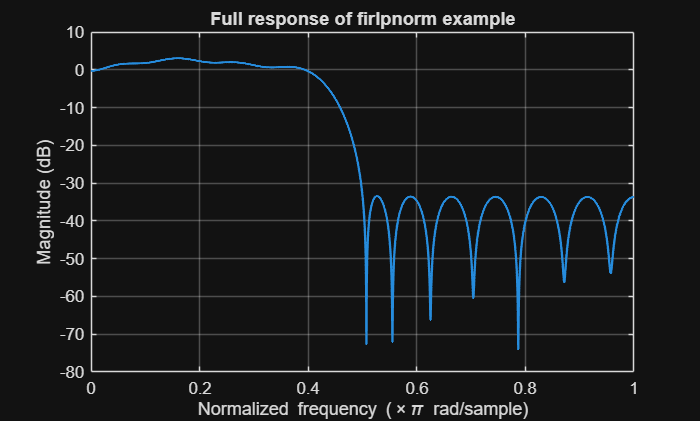

% b_demo = firlpnorm(22, ...                    % n:
%                                              % Filter order (number of taps = n+1 = 23).
%                                              % Controls approximation capability.
% 
%     [0 0.15 0.4 0.5 1], ...                  % f:
%                                              % Frequency grid (normalized to Nyquist = 1).
%                                              % These are the frequencies at which the desired
%                                              % amplitude 'a' is specified.
%                                              %
%                                              % Here:
%                                              %   0      -> start of passband
%                                              %   0.15   -> peak location in passband
%                                              %   0.4    -> end of passband
%                                              %   0.5    -> start of stopband
%                                              %   1      -> Nyquist
% 
%     [0 0.4 0.5 1], ...                       % edges:
%                                              % Band edges defining regions of interest.
%                                              %
%                                              % Interpreted as:
%                                              %   Passband:   0   to 0.4
%                                              %   Transition: 0.4 to 0.5
%                                              %   Stopband:   0.5 to 1
% 
%     [1 1.4 1 0 0], ...                       % a:
%                                              % Desired amplitude at each frequency in 'f'.
%                                              %
%                                              % This defines a NON-FLAT passband:
%                                              %   gain = 1      at DC
%                                              %   gain = 1.4    at 0.15 (passband peak)
%                                              %   gain = 1      at 0.4
%                                              %   gain = 0      in stopband
% 
%     [1 1 1 2 2], ...                         % w:
%                                              % Weights applied to the error at each frequency.
%                                              %
%                                              % Larger weight => error is penalized more.
%                                              %
%                                              % Here:
%                                              %   passband weights = 1
%                                              %   stopband weights = 2
%                                              %
%                                              % → Stopband accuracy is emphasized more.
% 
%     [2 128]);                                % p:
%                                              % Least-Pth norm specification (IMPORTANT).
%                                              %
%                                              % Must be a vector [p_min p_max].
%                                              %
%                                              % MATLAB uses continuation:
%                                              %   starts at p = 2 (least-squares-like)
%                                              %   increases toward p = 128 (near minimax)
%                                              %
%                                              % → Produces behaviour between least-squares
%                                              %   and equiripple design.

b_demo = firlpnorm(22, [0 0.15 0.4 0.5 1], [0 0.4 0.5 1], [1 1.4 1 0 0], [1 1 1 2 2], [2 128]);  

[H,w] = freqz(b_demo,1,4096);
f_norm = w/pi;              % normalized to Nyquist
mag = abs(H);

%% Full magnitude in dB
figure;
plot(f_norm,20*log10(mag+eps),'LineWidth',1.4);
grid on;
xlabel('Normalized frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
title('Full response of firlpnorm example');

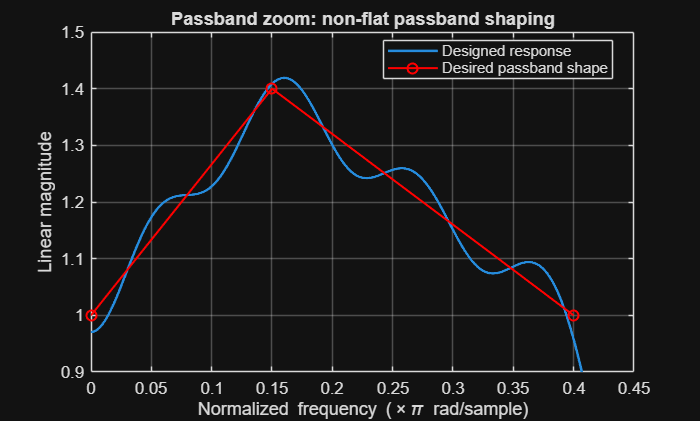


%% Passband zoom in linear magnitude
figure;
plot(f_norm,mag,'LineWidth',1.5); hold on;
plot([0 0.15 0.4],[1 1.4 1],'ro-','LineWidth',1.2,'MarkerSize',6);
grid on;
xlabel('Normalized frequency (\times\pi rad/sample)');
ylabel('Linear magnitude');
title('Passband zoom: non-flat passband shaping');
xlim([0 0.45]);
ylim([0.9 1.5]);
legend('Designed response','Desired passband shape','Location','Best');

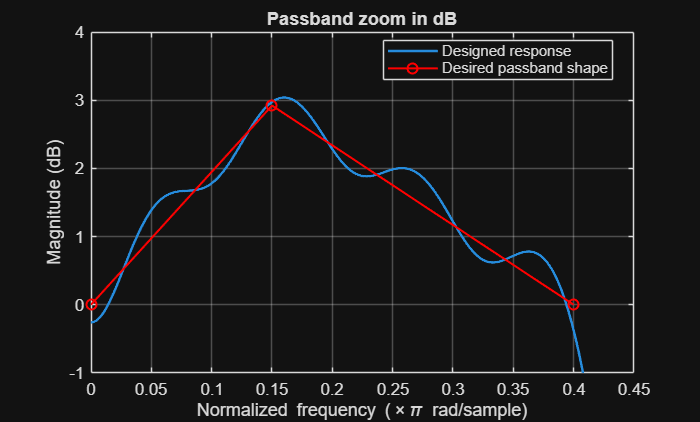


%% Passband zoom in dB
figure;
plot(f_norm,20*log10(mag+eps),'LineWidth',1.5); hold on;
plot([0 0.15 0.4],20*log10([1 1.4 1]),'ro-','LineWidth',1.2,'MarkerSize',6);
grid on;
xlabel('Normalized frequency (\times\pi rad/sample)');
ylabel('Magnitude (dB)');
title('Passband zoom in dB');
xlim([0 0.45]);
ylim([-1 4]);
legend('Designed response','Desired passband shape','Location','Best');

# IIR Filter Design Comparisons

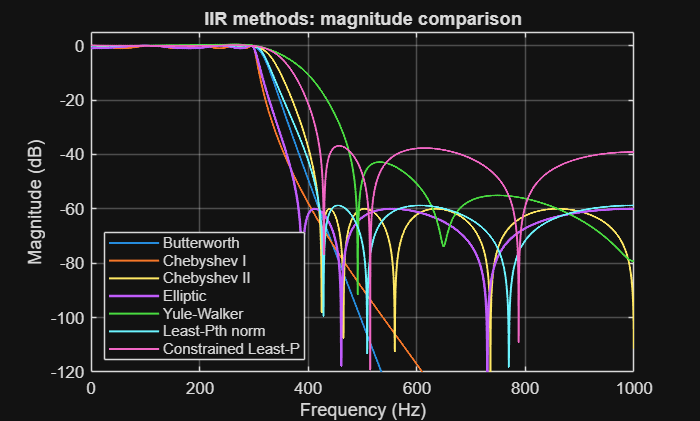

%% iir_method_comparison.m
% Visual comparison of common IIR design methods

clear; close all; clc;

%% Specifications
Fs  = 2000;      % Hz
Fp  = 300;       % Passband edge
Fst = 420;       % Stopband edge
Ap  = 1;         % Passband ripple (dB)
Ast = 60;        % Stopband attenuation (dB)

%% Classical methods using designfilt
d_butter = designfilt('lowpassiir', ...
    'PassbandFrequency', Fp, ...
    'StopbandFrequency', Fst, ...
    'PassbandRipple', Ap, ...
    'StopbandAttenuation', Ast, ...
    'SampleRate', Fs, ...
    'DesignMethod', 'butter');

d_cheby1 = designfilt('lowpassiir', ...
    'PassbandFrequency', Fp, ...
    'StopbandFrequency', Fst, ...
    'PassbandRipple', Ap, ...
    'StopbandAttenuation', Ast, ...
    'SampleRate', Fs, ...
    'DesignMethod', 'cheby1');

d_cheby2 = designfilt('lowpassiir', ...
    'PassbandFrequency', Fp, ...
    'StopbandFrequency', Fst, ...
    'PassbandRipple', Ap, ...
    'StopbandAttenuation', Ast, ...
    'SampleRate', Fs, ...
    'DesignMethod', 'cheby2');

d_ellip = designfilt('lowpassiir', ...
    'PassbandFrequency', Fp, ...
    'StopbandFrequency', Fst, ...
    'PassbandRipple', Ap, ...
    'StopbandAttenuation', Ast, ...
    'SampleRate', Fs, ...
    'DesignMethod', 'ellip');

%% Yule-Walker magnitude-shape fitting
f = [0 Fp Fst Fs/2]/(Fs/2);
m = [1 1 0 0];
nY = 8;
% Use yulewalk, inputs nY, f, m
[b_yw, a_yw] = yulewalk(nY, f, m);
hasYW = true;

%% Least-P norm / constrained Least-P norm if available
hasLPN = false;
hasLPNC = false;

try
    fp  = Fp/(Fs/2);
    fst = Fst/(Fs/2);

    % ------------------------------------------------------------
    % Least-Pth norm IIR design (iirlpnorm)
    % ------------------------------------------------------------

    % Frequency vector (NORMALIZED to Nyquist, so range is [0,1])
    % These are the frequency points where we specify the desired response.
    % IMPORTANT: must include all band-edge frequencies exactly.
    %
    % Interpretation:
    %   0   → DC
    %   fp  → passband edge
    %   fst → stopband edge
    %   1   → Nyquist frequency
    f = [0 fp fst 1];

    % Band-edge definition
    % This partitions the frequency axis into bands:
    %
    %   [0, fp]   → passband
    %   [fp, fst] → transition band (NOT directly constrained)
    %   [fst, 1]  → stopband
    %
    % For iirlpnorm, edges must match the endpoints of f.
    edges = [0 fp fst 1];

    % Desired amplitude at each frequency in f
    %
    % Interpretation:
    %   a = 1 in the passband → we want gain ≈ 1
    %   a = 0 in the stopband → we want attenuation
    %
    % NOTE:
    % The transition band is NOT explicitly enforced — the algorithm
    % will find the best way to connect the two bands.
    a = [1 1 0 0];

    % Weighting function
    %
    % This tells the optimizer how important each frequency point is.
    %
    % Here:
    %   passband weights = 1
    %   stopband weights = 5
    %
    % So:
    %   → errors in stopband are penalized more strongly
    %   → the design will push harder to reduce stopband leakage
    %
    % This is a key design knob in practice.
    w = [1 1 5 5];

    % P-norm range
    %
    % The algorithm solves a sequence of optimization problems
    % that gradually move from L2 norm (least squares) toward L∞ norm
    % (minimax / equiripple).
    %
    %   p = [2 128] means:
    %       start at p = 2   → smooth least-squares solution
    %       gradually increase toward p = 128 → near minimax behaviour
    %
    % This continuation helps convergence and avoids bad local minima.
    p = [2 128];

    % ------------------------------------------------------------
    % Perform the IIR design
    % ------------------------------------------------------------

    % Syntax:
    %   [b, a] = iirlpnorm(numOrd, denOrd, f, edges, a, w, p)
    %
    % Here:
    %   numOrd = 6 → numerator order
    %   denOrd = 6 → denominator order
    %
    % So we are designing a 6th-order IIR filter (biquad cascade internally).
    [b_lpn, a_lpn] = iirlpnorm(6, 6, f, edges, a, w, p);
    hasLPN = true;
    hasLPN = true;
catch
    warning('iirlpnorm not available. Skipping Least-Pth norm IIR.');
end

try
    % constrained least-pth norm IIR design
    %
    % Syntax used here:
    %   [b,a] = iirlpnormc(numOrd, denOrd, f, edges, a_des, w, maxPoleRadius)
    %
    % numOrd         = 6
    % denOrd         = 6
    % f              = frequency vector (must include the band edges)
    % edges          = band-edge frequencies
    % a_des          = desired amplitudes at the frequencies in f
    % w              = weighting vector
    % maxPoleRadius  = constrain poles to lie inside radius 0.8

    f_lpnc     = [0 fp fst 1];      % frequency points
    edges_lpnc = [0 fp fst 1];      % band edges
    a_lpnc_des = [1 1 0 0];         % desired response
    w_lpnc     = [1 1 1 1];         % weights
    rmax       = 0.8;               % maximum pole radius

    [b_lpnc, a_lpnc] = iirlpnormc(6, 6, f_lpnc, edges_lpnc, a_lpnc_des, w_lpnc, rmax);

    hasLPNC = true;
catch ME
    warning('iirlpnormc not available or failed: %s', ME.message);
    hasLPNC = false;
end

%% Frequency responses
nfft = 4096;
[Hbut, ff] = freqz(d_butter, nfft, Fs);
[Hc1,  ~]  = freqz(d_cheby1, nfft, Fs);
[Hc2,  ~]  = freqz(d_cheby2, nfft, Fs);
[Hell, ~]  = freqz(d_ellip,  nfft, Fs);
[Hyw, ~] = freqz(b_yw, a_yw, nfft, Fs);
if hasLPN
    [Hlpn, ~] = freqz(b_lpn, a_lpn, nfft, Fs);
end
if hasLPNC
    [Hlpnc, ~] = freqz(b_lpnc, a_lpnc, nfft, Fs);
end

%% Magnitude response
figure('Name','IIR Method Comparison: Magnitude');
plot(ff, 20*log10(abs(Hbut)+eps), 'LineWidth', 1.2); hold on;
plot(ff, 20*log10(abs(Hc1)+eps),  'LineWidth', 1.2);
plot(ff, 20*log10(abs(Hc2)+eps),  'LineWidth', 1.2);
plot(ff, 20*log10(abs(Hell)+eps), 'LineWidth', 1.5);
plot(ff, 20*log10(abs(Hyw)+eps), 'LineWidth', 1.2);
if hasLPN
    plot(ff, 20*log10(abs(Hlpn)+eps), 'LineWidth', 1.2);
end
if hasLPNC
    plot(ff, 20*log10(abs(Hlpnc)+eps), 'LineWidth', 1.2);
end
grid on;
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
title('IIR methods: magnitude comparison');
ylim([-120 5]);

leg = {'Butterworth','Chebyshev I','Chebyshev II','Elliptic'};
leg{end+1} = 'Yule-Walker';
if hasLPN
    leg{end+1} = 'Least-Pth norm';
end
if hasLPNC
    leg{end+1} = 'Constrained Least-P';
end
legend(leg, 'Location', 'SouthWest');

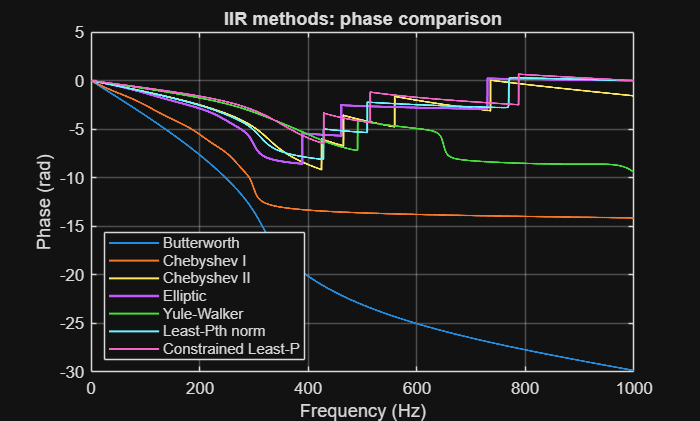


%% Phase
figure('Name','IIR Method Comparison: Phase');
plot(ff, unwrap(angle(Hbut)), 'LineWidth', 1.2); hold on;
plot(ff, unwrap(angle(Hc1)),  'LineWidth', 1.2);
plot(ff, unwrap(angle(Hc2)),  'LineWidth', 1.2);
plot(ff, unwrap(angle(Hell)), 'LineWidth', 1.5);
plot(ff, unwrap(angle(Hyw)), 'LineWidth', 1.2);
if hasLPN
    plot(ff, unwrap(angle(Hlpn)), 'LineWidth', 1.2);
end
if hasLPNC
    plot(ff, unwrap(angle(Hlpnc)), 'LineWidth', 1.2);
end
grid on;
xlabel('Frequency (Hz)');
ylabel('Phase (rad)');
title('IIR methods: phase comparison');
legend(leg, 'Location', 'SouthWest');

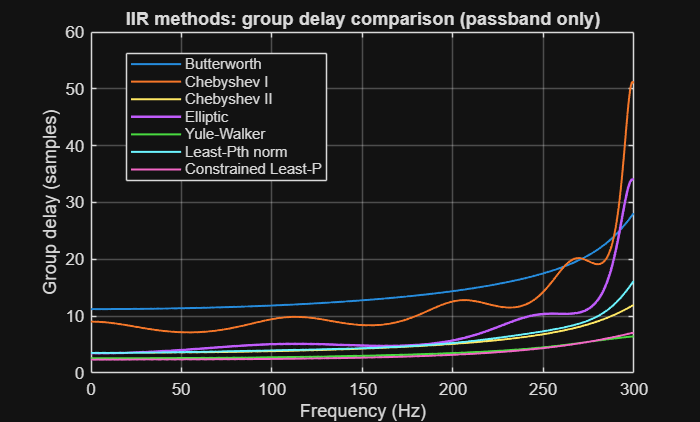


%% ------------------------------------------------------------
%% Group delay: better visualization
%% ------------------------------------------------------------

Ngd = 2048;   % use the SAME number of points for grpdelay and freqz

[gd_but, fg] = grpdelay(d_butter, Ngd, Fs);
[gd_c1,  ~]  = grpdelay(d_cheby1, Ngd, Fs);
[gd_c2,  ~]  = grpdelay(d_cheby2, Ngd, Fs);
[gd_ell, ~]  = grpdelay(d_ellip,  Ngd, Fs);
[gd_yw,  ~]  = grpdelay(b_yw, a_yw, Ngd, Fs);

if hasLPN
    [gd_lpn, ~] = grpdelay(b_lpn, a_lpn, Ngd, Fs);
end
if hasLPNC
    [gd_lpnc, ~] = grpdelay(b_lpnc, a_lpnc, Ngd, Fs);
end

%% Compute magnitude responses on the SAME grid as grpdelay
[Hbut_gd, ~] = freqz(d_butter, Ngd, Fs);
[Hc1_gd,  ~] = freqz(d_cheby1, Ngd, Fs);
[Hc2_gd,  ~] = freqz(d_cheby2, Ngd, Fs);
[Hell_gd, ~] = freqz(d_ellip,  Ngd, Fs);
[Hyw_gd,  ~] = freqz(b_yw, a_yw, Ngd, Fs);

if hasLPN
    [Hlpn_gd, ~] = freqz(b_lpn, a_lpn, Ngd, Fs);
end
if hasLPNC
    [Hlpnc_gd, ~] = freqz(b_lpnc, a_lpnc, Ngd, Fs);
end

%% 1) PASSBAND-ONLY GROUP DELAY
mask_pb = fg <= Fp;

figure('Name','IIR Method Comparison: Group delay (passband only)');
plot(fg(mask_pb), gd_but(mask_pb), 'LineWidth', 1.2); hold on;
plot(fg(mask_pb), gd_c1(mask_pb),  'LineWidth', 1.2);
plot(fg(mask_pb), gd_c2(mask_pb),  'LineWidth', 1.2);
plot(fg(mask_pb), gd_ell(mask_pb), 'LineWidth', 1.5);
plot(fg(mask_pb), gd_yw(mask_pb),  'LineWidth', 1.2);
if hasLPN
    plot(fg(mask_pb), gd_lpn(mask_pb), 'LineWidth', 1.2);
end
if hasLPNC
    plot(fg(mask_pb), gd_lpnc(mask_pb), 'LineWidth', 1.2);
end
grid on;
xlabel('Frequency (Hz)');
ylabel('Group delay (samples)');
title('IIR methods: group delay comparison (passband only)');
legend(leg, 'Location', 'Best');

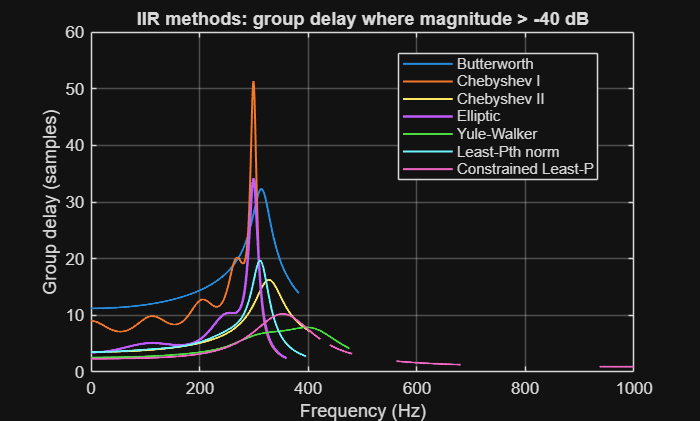


%% 2) MAGNITUDE-MASKED GROUP DELAY
thresh_dB = -40;   % only show delay where |H| > -40 dB

gd_but_m = gd_but;
gd_c1_m  = gd_c1;
gd_c2_m  = gd_c2;
gd_ell_m = gd_ell;
gd_yw_m  = gd_yw;

gd_but_m(20*log10(abs(Hbut_gd)+eps) < thresh_dB) = NaN;
gd_c1_m(20*log10(abs(Hc1_gd)+eps)   < thresh_dB) = NaN;
gd_c2_m(20*log10(abs(Hc2_gd)+eps)   < thresh_dB) = NaN;
gd_ell_m(20*log10(abs(Hell_gd)+eps) < thresh_dB) = NaN;
gd_yw_m(20*log10(abs(Hyw_gd)+eps)   < thresh_dB) = NaN;

if hasLPN
    gd_lpn_m = gd_lpn;
    gd_lpn_m(20*log10(abs(Hlpn_gd)+eps) < thresh_dB) = NaN;
end

if hasLPNC
    gd_lpnc_m = gd_lpnc;
    gd_lpnc_m(20*log10(abs(Hlpnc_gd)+eps) < thresh_dB) = NaN;
end

figure('Name','IIR Method Comparison: Group delay (magnitude-masked)');
plot(fg, gd_but_m, 'LineWidth', 1.2); hold on;
plot(fg, gd_c1_m,  'LineWidth', 1.2);
plot(fg, gd_c2_m,  'LineWidth', 1.2);
plot(fg, gd_ell_m, 'LineWidth', 1.5);
plot(fg, gd_yw_m,  'LineWidth', 1.2);
if hasLPN
    plot(fg, gd_lpn_m, 'LineWidth', 1.2);
end
if hasLPNC
    plot(fg, gd_lpnc_m, 'LineWidth', 1.2);
end
grid on;
xlabel('Frequency (Hz)');
ylabel('Group delay (samples)');
title(sprintf('IIR methods: group delay where magnitude > %d dB', thresh_dB));
legend(leg, 'Location', 'Best');
xlim([0 Fs/2]);

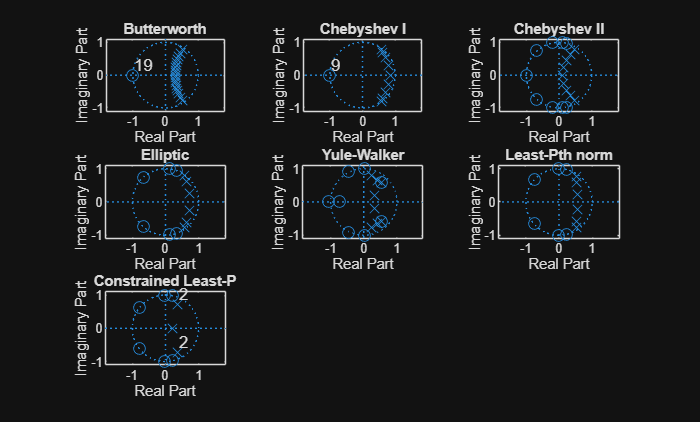


%% Pole-zero plots for all available IIR filters

% Build a list of filter names and coefficient/object representations
pzNames = {};
pzType  = {};   % 'obj' or 'ba'
pzData  = {};

% Classical digitalFilter objects
pzNames{end+1} = 'Butterworth';
pzType{end+1}  = 'obj';
pzData{end+1}  = d_butter;

pzNames{end+1} = 'Chebyshev I';
pzType{end+1}  = 'obj';
pzData{end+1}  = d_cheby1;

pzNames{end+1} = 'Chebyshev II';
pzType{end+1}  = 'obj';
pzData{end+1}  = d_cheby2;

pzNames{end+1} = 'Elliptic';
pzType{end+1}  = 'obj';
pzData{end+1}  = d_ellip;

% Yule-Walker
pzNames{end+1} = 'Yule-Walker';
pzType{end+1}  = 'ba';
pzData{end+1}  = {b_yw, a_yw};

% Least-Pth norm, if available
if hasLPN
    pzNames{end+1} = 'Least-Pth norm';
    pzType{end+1}  = 'ba';
    pzData{end+1}  = {b_lpn, a_lpn};
end

% Constrained Least-Pth norm, if available
if hasLPNC
    pzNames{end+1} = 'Constrained Least-P';
    pzType{end+1}  = 'ba';
    pzData{end+1}  = {b_lpnc, a_lpnc};
end

% Number of filters to plot
nPZ = numel(pzNames);

% Choose a subplot layout automatically
nCols = ceil(sqrt(nPZ));
nRows = ceil(nPZ / nCols);

figure('Name','Pole-zero plots: all IIR methods');

for k = 1:nPZ
    subplot(nRows, nCols, k);

    if strcmp(pzType{k}, 'obj')
        % zplane can directly take a filter object
        zplane(pzData{k});
    else
        ba = pzData{k};
        % zplane can take the filter coefficients
        zplane(ba{1}, ba{2});
    end

    title(pzNames{k});
end


%% Order summary
fprintf('\nIIR comparison summary\n');


IIR comparison summary


fprintf('Butterworth order = %d\n', filtord(d_butter));

Butterworth order = 19


fprintf('Chebyshev I order = %d\n', filtord(d_cheby1));

Chebyshev I order = 9


fprintf('Chebyshev II order = %d\n', filtord(d_cheby2));

Chebyshev II order = 9


fprintf('Elliptic order    = %d\n', filtord(d_ellip));

Elliptic order    = 6


fprintf('Yule-Walker order = %d\n', max(length(a_yw), length(b_yw)) - 1);

Yule-Walker order = 8


if hasLPN
    fprintf('Least-P order     = %d/%d\n', length(b_lpn)-1, length(a_lpn)-1);
end

Least-P order     = 6/6


if hasLPNC
    fprintf('Constrained L-P order = %d/%d\n', length(b_lpnc)-1, length(a_lpnc)-1);
end

Constrained L-P order = 6/6


### Things to Consider:

Which family gives the sharpest transition for the smallest order - Elliptic

Which family has the smoothest passband - Butterworth